% Define the symbolic variables
syms W2S L2D rho V C_D_0 A e
 
 
% Define the equation
eqn = W2S == L2D * rho/2 * V^2 * C_D_0 + L2D*W2S^2*2/(rho*pi*A*e*V^2)

$$eqn = \mathrm{W2S}=\frac{C_{D,0}\,\mathrm{L2D}\,V^{2}\,\rho }{2}+\frac{2\,\mathrm{L2D}\,{\mathrm{W2S}}^{2}}{A\,V^{2}\,e\,\rho \,\pi }$$

eqn = W2S == L2D * rho/2 * V^2 * (C_D_0 + (W2S*2/(rho*V^2))^2/(pi*A*e))

$$eqn = \mathrm{W2S}=\frac{\mathrm{L2D}\,V^{2}\,\rho \,\left(C_{D,0}+\frac{4\,{\mathrm{W2S}}^{2}}{A\,V^{4}\,e\,\rho^{2}\,\pi }\right)}{2}$$

 

% Substitute values for variables
% values = {rho, V, CD0, A, e, L_D}; % List of variables to substitute
% subs_values = {1.225, 50, 0.031, 40, 0.9, 30}; % Corresponding values for the variables

values = {rho, V, C_D_0, e, L2D}; % List of variables to substitute
subs_values = {1.0834, convvel(50,"kts","m/s"), 0.0075, 0.9, 30}; % Corresponding values for the variables
 
 
 
 
% Solve the equation
W_S_solution = solve(eqn, W2S);
W_S_solution

$$W\_S\_solution = \left(\begin{array}{c} -\frac{A\,V^{2}\,e\,\rho \,\sqrt{\pi }\,\left(\sqrt{-\frac{4\,C_{D,0}\,{\mathrm{L2D}}^{2}-\pi \,A\,e}{A\,e}}-\sqrt{\pi }\right)}{4\,\mathrm{L2D}}\\ \frac{A\,V^{2}\,e\,\rho \,\sqrt{\pi }\,\left(\sqrt{-\frac{4\,C_{D,0}\,{\mathrm{L2D}}^{2}-\pi \,A\,e}{A\,e}}+\sqrt{\pi }\right)}{4\,\mathrm{L2D}} \end{array}\right)$$


assume(A,'positive')
A_solution = solve(eqn,A)

$$A\_solution = -\frac{4\,{\mathrm{W2S}}^{2}}{V^{4}\,e\,\rho^{2}\,\pi \,\left(C_{D,0}-\frac{2\,\mathrm{W2S}}{\mathrm{L2D}\,V^{2}\,\rho }\right)}$$

A_solution_clamped = A_solution * heaviside(A_solution)

$$A\_solution\_clamped = -\frac{4\,{\mathrm{W2S}}^{2}\,\mathrm{heaviside}\left(\frac{4\,\mathrm{L2D}\,{\mathrm{W2S}}^{2}}{V^{2}\,e\,\rho \,\pi \,\left(2\,\mathrm{W2S}-C_{D,0}\,\mathrm{L2D}\,V^{2}\,\rho \right)}\right)}{V^{4}\,e\,\rho^{2}\,\pi \,\left(C_{D,0}-\frac{2\,\mathrm{W2S}}{\mathrm{L2D}\,V^{2}\,\rho }\right)}$$

A_solution = real(A_solution * (1-heaviside(A_solution)))

$$A\_solution = 4\,\mathrm{real}\left(\frac{{\mathrm{W2S}}^{2}\,\left(\mathrm{heaviside}\left(\frac{4\,\mathrm{L2D}\,{\mathrm{W2S}}^{2}}{V^{2}\,e\,\rho \,\pi \,\left(2\,\mathrm{W2S}-C_{D,0}\,\mathrm{L2D}\,V^{2}\,\rho \right)}\right)-1\right)}{V^{4}\,e\,\rho^{2}\,\pi \,\left(C_{D,0}-\frac{2\,\mathrm{W2S}}{\mathrm{L2D}\,V^{2}\,\rho }\right)}\right)$$

eqn_A_substituted = subs(A_solution, values, subs_values)

$$eqn\_A\_substituted = -\frac{11664000000000\,\mathrm{real}\left(\frac{{\mathrm{W2S}}^{2}\,\left(\mathrm{heaviside}\left(\frac{1555200000000000\,{\mathrm{W2S}}^{2}}{1161236873\,\pi \,\left(14400000\,\mathrm{W2S}-1161236873\right)}\right)-1\right)}{\pi \,\left(\frac{108000\,\mathrm{W2S}}{1161236873}-\frac{3}{400}\right)}\right)}{1348471075214818129}$$

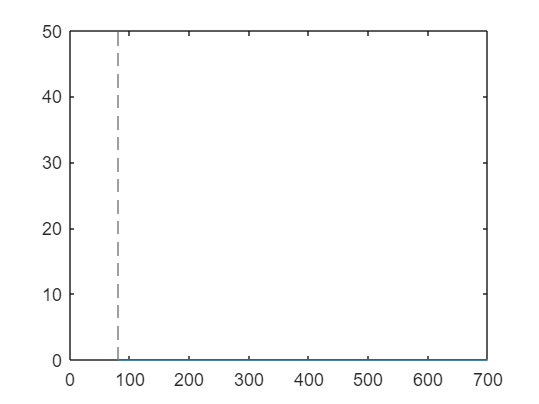

fplot(eqn_A_substituted, [0,700])
ylim([0,50])


 
% Substitute the values into the equation
eqn_substituted = round(subs(W_S_solution, values, subs_values))

$$eqn\_substituted = \left(\begin{array}{c} \mathrm{round}\left(-\frac{1161236873\,A\,\sqrt{\pi }\,\left(\sqrt{\frac{10\,\left(\frac{9\,\pi \,A}{10}-27\right)}{9\,A}}-\sqrt{\pi }\right)}{216000000}\right)\\ \mathrm{round}\left(\frac{1161236873\,A\,\sqrt{\pi }\,\left(\sqrt{\frac{10\,\left(\frac{9\,\pi \,A}{10}-27\right)}{9\,A}}+\sqrt{\pi }\right)}{216000000}\right) \end{array}\right)$$

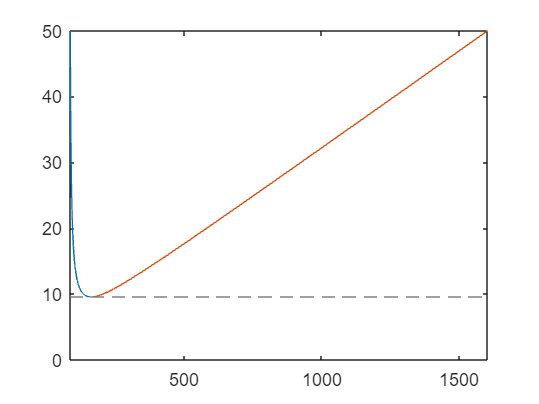

fplot(eqn_substituted, [0,50])
view([90,-90])